# Intro on machine learning classifiers (vol I). Rationale.

**Author**: Javier Ortiz-Tudela (Goethe University)

**Email**: [ortiztudela@psych.uni-frankfurt.de](mailto:ortiztudela@psych.uni-frankfurt.de)

**Created on**: 06/04/2020

**Last update on**: 12/04/2020

## Initialize some stuff.

Just run this section. Press Ctrl +

 Enter.

clear; close all
clc

## Intoduction

What is machine learning? Machine learning, decoding, mvpa, classification, classifier based analysis.

## Practical example (human learning)

Here you have two datasets. They correspond to two conditions or classes (1 and 2) with each number representing the measure of our variable of interest for a set of 8 participants. Can you see a pattern that distinguishes them?

% Condition 1 data
array1 = [51; 53; 55; 57; 59; 61; 63; 65]; 
labels1 = [1; 1; 1; 1; 1; 1; 1; 1]; % These are just the labels that code the condition of each datapoint

% Condition 2 data
array2 = [32; 34; 36; 38; 40; 42; 44; 46];
labels2 = [2; 2; 2; 2; 2; 2; 2; 2]; % These are just the labels that code the condition of each datapoint

% What is the best way of knowing whether you learn the pattern or not? Test your self:
test_observation=34;

% Is test_observation a member of 1 or 2? Replace the "[]" with your answer.
your_prediction=[2];

% If we know the ground truth, we can check how good your learning was. 
test_label=2;
if your_prediction == test_label;accuracy=1; sprintf('Yay! You did great!')
else; accuracy=0;sprintf('Cueck. You did not identify the class correctly')
end

ans = 'Yay! You did great!'

## Can machines do that?

We will now train an algorithm to distinguish between these same two conditions / classes. Then we will test the algorithm with the same test observation as above.

% Put all of the 'training' observations together
train_data=[array1; array2];
train_labels=[labels1;labels2];

% Train the classifier
classifier = fitcsvm(train_data, train_labels);

% We will use the same label as before. We do not need to define it again,
% we can just re-use it. On doing so, we will avoid hard-coding.

% Ask the classifier to predict
classifier_prediction=predict(classifier, test_observation)

classifier_prediction = 2

sprintf('The classifier "predicts" the observation "%d" belongs to class %d', ...
    test_observation, classifier_prediction)

ans = 'The classifier "predicts" the observation "11" belongs to class 2'


% Compute performance
acc=classifier_prediction==test_label;
if classifier_prediction == test_label;accuracy=1; sprintf('Yay! The classifier guessed it correctly!')
else; accuracy=0;sprintf('The classifier did not gess the class correctly')
end

ans = 'Yay! The classifier guessed it correctly!'

So it looks like our classifier does pretty well or, at least, it does as good as you (probably) do.

## Validation

There is yet a better (more restrictive) way of assessing learning: Test on observations that are *different* from the study sets.

% We select a new observation from outside our dataset.
test_observation=11;

% We will test your knowledge here.
% Same as above: is test_observation a member of 1 or 2? Replace the "[]" with your answer
your_prediction=[];

% We can ask the classifier that we trained before.
classifier_prediction=predict(classifier, test_observation)

classifier_prediction = 2

sprintf('The classifier thinks the observation "%d" belongs to class %d \n and your prediction is %d.', ...
    test_observation, classifier_prediction, your_prediction)

ans =     'The classifier thinks the observation "11" belongs to class 2 
      and your prediction is .'


Is there a disrepancy between your prediction and the classifier's? Let's check who's right.

% In this case, we know the true label 
test_label=2; % True label

% Assess performance
if your_prediction == test_label;accuracy=1; sprintf('Yay! You did great!')
else; accuracy=0;sprintf('Cueck. You did not identify the class correctly.')
end

ans = 'Cueck. You did not identify the class correctly.'


% Compute performance
acc=classifier_prediction==test_label;
if acc == 1;sprintf('The classifier guessed correctly!')
else; sprintf('The classifier failed.')
end

ans = 'The classifier guessed correctly!'

With reduced datasets such as this one, we can visualize the observations to get a better intuition of what the classifier is doing. This will be impossible to do for more complex datasets, but for now it can help.

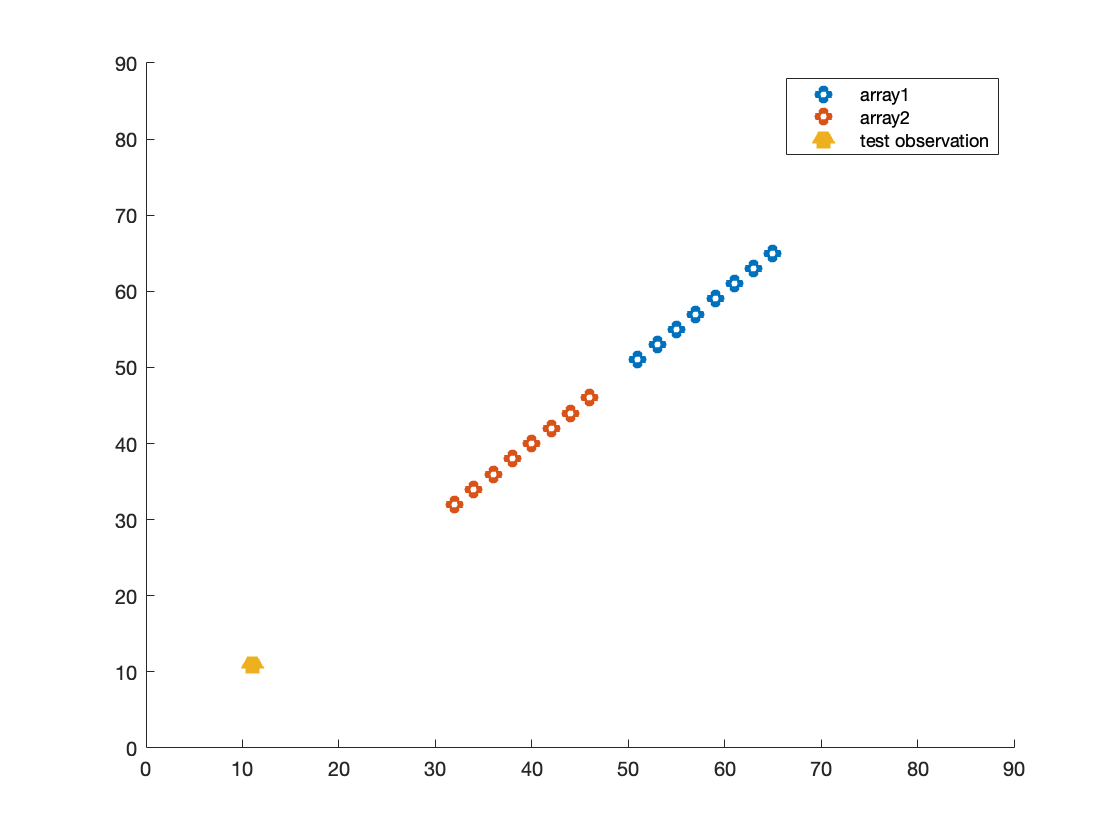

% Display data sets 
figure; hold on
plot(array1, array1, 'o', 'LineWidth', 3);plot(array2, array2, 'o', 'LineWidth', 3); 
plot(test_observation, test_observation, '^', 'LineWidth', 5);
axis([0 90 00 90]);legend({'array1'; 'array2';'test observation'})

Can you guess the rule that the classifier has learned? Discuss this with your peers before moving on.

## Cross-validation

We have seen that is very important to have independent validation. However, this can be tricky sometimes as it implies that you need to have *data* that is not part of your *data. *Namely, it would require you to collect twice as many datasets as you originally intended. And we all know that collecting data is expensive. 

Cross-validation is a technique with which we can subsample our original dataset to create independent sub-datasets that then we can use to validate our training. 

Let's see how it works with a practical example.

% We start with the same data as in the example above
data=[array1; array2];
data_labels=[labels1;labels2];

**First step**: We divide the original data set into two independent (non-overlapping) subsets. In this examples we will divide our observations in odd and even. Note that we are dividing the observations and the corresponding labels.

 % Odd observations
train_data=data(1:2:length(data));
train_labels=data_labels(1:2:length(data_labels));

% Even observations
test_data=data(2:2:length(data)); 
test_labels=data_labels(2:2:length(data_labels));

Now we can train the classifier in one of the datasets and test on the other one.

% Train the algorithm on odd observations
classifier = fitcsvm(train_data, train_labels);

% Test on even observations
classifier_prediction=predict(classifier, test_data)

classifier_prediction =      1
     1
     1
     1
     2
     2
     2
     2



% Compute and store performance 
acc_fold(1)=mean(classifier_prediction==test_labels)

acc_fold = 1

**Second step**: We can swap our training and test sets and repeat the procedure. Note that we have just swap the names of the variables: what was train before now it becomes test and what was test becomes train.

 % Odd observations
test_data=data(1:2:length(data));
test_labels=data_labels(1:2:length(data_labels));

% Even observations
train_data=data(2:2:length(data)); 
train_labels=data_labels(2:2:length(data_labels));

Now we can repeate the training with the swapped datasets. We will also store performance in a separate entry so that it does not override the previous one.

% Train the algorithm on even observations
classifier2 = fitcsvm(train_data, train_labels);

% Test on odd observations
classifier_prediction=predict(classifier, test_data)

classifier_prediction =      1
     1
     1
     1
     2
     2
     2
     2



% Compute and store performance 
acc_fold(2)=mean(classifier_prediction==test_labels);

Each one of this steps (usually refered to as *folds*) outputs an accuracy measure. If we average them, we will have a measure of accuracy that has been independently validated (on each fold) while not losing any data.

final_acc=mean(acc_fold)

final_acc = 1

## Another example of cross-validation. Leave-one-out.

Can you set a cross-validation scheme yourself? This would require a bit of MATLAB skills so if you feel like you do not have those yet, try to at least conceptually understand how it would work.